# ATS Mandatory Assignment 05

% **Assignment 5 (Mandatory)**  
% **MatNr:6940188**
% **MatNr:**
% **Submission Date:** December 12th, 2025


if isdeployed
    scriptFolder = ctfroot; 
else
    scriptFolder = fileparts(matlab.desktop.editor.getActiveFilename);
end

if isempty(scriptFolder)
    error('Could not determine the folder of the currently running script.');
end

cd(scriptFolder);

disp(['Current folder changed to: ', scriptFolder]);

Current folder changed to: C:\Users\sovai\OneDrive\Desktop\time_series_ass


## Task 1: Simulating an ARMA(1,1) Process

%%% Task 1.1: We define the ARMA Simulator Function

function yt = ARMA_simulator(T, c, phi, theta, nu, y0)
    yt = zeros(T, 1); 
    epsilon = trnd(nu, T, 1); 
    yt(1) = y0;
    epsilon_prev = 0;
    for t = 2:T
        yt(t) = c + phi * yt(t-1) + epsilon(t) + theta * epsilon_prev;
        epsilon_prev = epsilon(t); 
    end
end

%%% Task 1.2: We will now simulate the process
% Parameters
c = 2;              
phi = 0.95;         
theta = 0.25;      
nu = 4;             
T = 800;            
y0 = 40;            
burn_in = 50;      

% We compute the expected value of the process
expected_value = c / (1 - phi);
disp(['Expected Value: ', num2str(expected_value)]);

Expected Value: 40


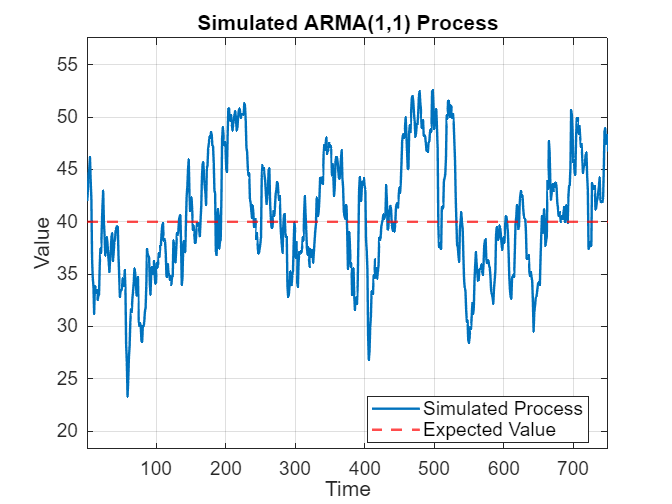


% Here we use the above defined ARMA_simulator function to generate the time series
rng(42);  % setting seed for reproducibility to ensure consistent results
series = ARMA_simulator(T, c, phi, theta, nu, y0);

% We remove burn-in phase
y = series((burn_in + 1):end);

%%% Task 1.3: Here we visualize the simulated ARMA(1,1) process
figure; 
hold on; 
plot(1:(T - burn_in), y, 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]);
yline(expected_value, '--r', 'LineWidth', 1.5, ...
    'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'bottom');
title('Simulated ARMA(1,1) Process', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Time', 'FontSize', 12); 
ylabel('Value', 'FontSize', 12); 
grid on;
xlim([1 T - burn_in]); 
ylim([min(y) - 5, max(y) + 5]);
legend({'Simulated Process', 'Expected Value'}, 'Location', 'best', 'FontSize', 12);
set(gca, 'FontSize', 12, 'Box', 'on'); 
hold off;

## Task 2: Unit Root Tests

%%% Task 2.2: We estimate the series with OLS

% Response Variable
yt = y(2:end);

% Lagged Variable
yt_lag = y(1:end-1);

% Constructing design matrix
X = [ones(length(yt_lag), 1), yt_lag];

% We now compute OLS estimates
b = (X' * X) \ (X' * yt);

% Extracting parameters
alpha_hat = b(1); 
rho_hat = b(2);

% Predictions and residuals
y_pred = X * b;          
residuals = yt - y_pred;

% Estimating variance of residuals
s_squared = (1 / (length(yt) - 2)) * sum(residuals .^ 2);

% Covariance matrix
Cov_b = s_squared * inv(X' * X);

% Standard errors
s_errors = sqrt(diag(Cov_b));
s_error_alpha = s_errors(1); 
s_error_rho = s_errors(2);  

disp('Estimated coefficients (βˆ):');

Estimated coefficients (βˆ):


disp(['c (constant): ', num2str(b(1))]); 

c (constant): 1.4638


disp(['φ (AR parameter): ', num2str(b(2))]); 

φ (AR parameter): 0.96393


disp('Standard Errors (s.e.):');

Standard Errors (s.e.):


disp(['s.e.(c): ', num2str(s_error_alpha)]); 

s.e.(c): 0.40172


disp(['s.e.(φ): ', num2str(s_error_rho)]);

s.e.(φ): 0.0098452


%%% Task 2.3: Next we perform Dickey-Fuller test

% We calculate t-statistic
phi_hat = b(2);         
se_phi = s_errors(2);   
t_stat = (phi_hat - 1) / se_phi;
disp(['t-statistic: ', num2str(t_stat)]);

t-statistic: -3.6633


% Comparing with critical value
critical_value = -2.86; 

if t_stat < critical_value
    disp('Reject the null hypothesis (H0: φ = 1). The series is stationary.');
else
    disp('Fail to reject the null hypothesis (H0: φ = 1). The series is non-stationary.');
end

Reject the null hypothesis (H0: φ = 1). The series is stationary.


## Task 3: Constructing the Conditional Log Likelihood

%%% Helper functions for Task 3

% 1st helper function: loglikelihood contributions
function logL_contributions = ml_contributions(params, y)
    % We first extract parameters
    c = params(1);
    phi = params(2);
    theta = params(3);
    nu = params(4);
    
    % Then we initialize variables
    T = length(y);
    epsilons = zeros(T, 1); 
    logL_contributions = zeros(T-1, 1);
    
    % Next we compute the series of innovations ε_t
    for t = 2:T
        epsilons(t) = y(t) - c - phi * y(t-1) - theta * epsilons(t-1);
    end

    % Dropping ε1 (the first innovation)
    epsilons = epsilons(2:end);
    
    % Computing log likelihood contributions
    for t = 1:(T-1)
        logL_contributions(t) = gammaln((nu + 1) / 2) ...
                                - gammaln(nu / 2) ...
                                - 0.5 * log(nu * pi) ...
                                - (nu + 1) / 2 * log(1 + (epsilons(t)^2 / nu));
    end
end

% 2nd helper function: loglikelihood
function total_logL = loglikelihood(params, y)
    logL_contributions = ml_contributions(params, y);

    % Total log likelihood: summing the contributions
    total_logL = sum(logL_contributions);
end

% Case (a) parameters
params_a = [2; 0.95; 0.25; 4];

% Now we compute the total log likelihood for case (a)
total_logL_a = loglikelihood(params_a, y);

disp(['Total conditional log likelihood for case a): ', num2str(total_logL_a)]);

Total conditional log likelihood for case a): -1298.8673


% Case (b) parameters
params_b = [1.5; 0.75; 0.5; 6];

% We compute the total log likelihood for case (b)
total_logL_b = loglikelihood(params_b, y);

disp(['Total conditional log likelihood for case b): ', num2str(total_logL_b)]);

Total conditional log likelihood for case b): -5515.3011


## Task 4: Parameter Estimation with Maximum Likelihood

% Helper function for task 4, which computes the negative total conditional log likelihood for ARMA(1,1)
function negLogL = neg_loglikelihood(params, y)
    logL_contributions = ml_contributions(params, y);
    negLogL = -sum(logL_contributions);
end

% CML toolbox
addpath('CML\CML');

% Starting values
x0 = [1.5; 0.75; 0.5; 5];

% Defining optimization settings for fminsearch algorithm
options = optimset('Display', 'iter', 'TolX', 1e-40, 'TolFun', 1e-40, ...
                   'MaxIter', 1e10, 'MaxFunEvals', 100000);

% We now estimate parameters by minimizing the negative log likelihood
[x, f, g, cov, retcode] = CML(@neg_loglikelihood,   ...  
                              @ml_contributions,    ...  
                              y,                    ...  
                              x0,                   ...  
                              1,                    ...  
                              1,                    ...  
                              options);             ...  


 
 Iteration   Func-count         f(x)         Procedure
     0            1           5175.4         
     1            5          4454.83         initial simplex
     2            6          4454.83         reflect
     3            7          4454.83         reflect
     4            9          3809.91         expand
     5           11          2789.29         expand
     6           12          2789.29         reflect
     7           14          1616.25         expand
     8           16          1480.17         reflect
     9           18          1360.02         reflect
    10           19          1360.02         reflect
    11           21          1360.02         contract outside
    12           23          1360.02         contract inside
    13           25          1360.02         contract inside
    14           27          1360.02         contract inside
    15           29          1360.02         contract inside
    16           31          1354.59         contract ou

disp('Optimized parameters = ');

Optimized parameters = 


disp(x);

    2.2312
    0.9452
    0.2837
    3.4691



disp('Minimum negative log-likelihood = ');

Minimum negative log-likelihood = 


disp(f);

   1.2971e+03



disp('Gradient at optimum = ');

Gradient at optimum = 


disp(g);

   1.0e-05 *

   -0.0004
   -0.3212
   -0.0003
   -0.0000



disp('Covariance matrix of estimates = ');

Covariance matrix of estimates = 


disp(cov);

    0.1683   -0.0041    0.0031    0.0030
   -0.0041    0.0001   -0.0001   -0.0001
    0.0031   -0.0001    0.0010   -0.0001
    0.0030   -0.0001   -0.0001    0.1298



disp(['Exit flag from fminsearch = ', num2str(retcode)]);

Exit flag from fminsearch = 1


% We store the optimized parameters and covariance matrix
paramEst = x;      
covEst = cov;      

% Next we compute standard errors
SE = sqrt(diag(covEst));

% Constructing 95% confidence intervals
zVal = 1.96; 
CI_lower = paramEst - zVal .* SE;
CI_upper = paramEst + zVal .* SE;

paramNames = {'c', 'phi', 'theta', 'nu'};
fprintf('\nParameter Estimates with 95%% CIs:\n');


Parameter Estimates with 95% CIs:


for i = 1:length(paramEst)
    fprintf('%s: Estimate = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', ...
        paramNames{i}, paramEst(i), SE(i), CI_lower(i), CI_upper(i));
end

c: Estimate = 2.2312, SE = 0.4102, CI = [1.4271, 3.0352]
phi: Estimate = 0.9452, SE = 0.0100, CI = [0.9255, 0.9648]
theta: Estimate = 0.2837, SE = 0.0309, CI = [0.2231, 0.3443]
nu: Estimate = 3.4691, SE = 0.3603, CI = [2.7630, 4.1752]


%%% Task 4.4: Perform t-test for H0: φ = 0.8
% We test the null hypothesis H0: φ = 0.8 at a 5% significance level (two-sided test)
phiEst = paramEst(2); 
phiSE = SE(2);        

% Now we compute the t-statistic
tStat = (phiEst - 0.8) / phiSE;

% Critical value
critVal = 1.96;

fprintf('\nT-test for H0: phi = 0.8\n');


T-test for H0: phi = 0.8


fprintf('   Estimate of phi = %.4f\n', phiEst);

   Estimate of phi = 0.9452


fprintf('   Standard Error   = %.4f\n', phiSE);

   Standard Error   = 0.0100


fprintf('   Test statistic   = %.4f\n', tStat);

   Test statistic   = 14.4996


if abs(tStat) > critVal
    fprintf('   => Reject H0 at the 5%% level (|tStat| > 1.96).\n\n');
else
    fprintf('   => Fail to reject H0 at the 5%% level.\n\n');
end

   => Reject H0 at the 5% level (|tStat| > 1.96).



%%% Task 4.5: computing two-Sided p-value
pValue = 2 * (1 - normcdf(abs(tStat))); 
fprintf('Test statistic for H0: phi = 0.8 is tStat = %.4f\n', tStat);

Test statistic for H0: phi = 0.8 is tStat = 14.4996


fprintf('Two-sided p-value = %.6f\n', pValue);

Two-sided p-value = 0.000000


if pValue < 0.05
    fprintf('=> p-value < 0.05 => Reject H0 at 5%% level.\n\n');
else
    fprintf('=> p-value >= 0.05 => Fail to reject H0 at 5%% level.\n\n');
end

=> p-value < 0.05 => Reject H0 at 5% level.



%%% Task 4.6: here we simulate a longer ARMA(1,1) series (T = 50,000) and re-estimate parameters

% Parameters
c = 2;              
phi = 0.95;         
theta = 0.25;       
nu = 4;             
T = 50000;          
y0 = c / (1 - phi); 

% Simulating the ARMA(1,1) process
rng(200); % Set seed for reproducibility
series = ARMA_simulator(T, c, phi, theta, nu, y0);

% Updating the series
y = series((burn_in+1):end);

% Now we will re-estimate parameters
[x, f, g, cov, retcode] = CML(@neg_loglikelihood,   ...
                              @ml_contributions,    ...
                              y,                    ...
                              x0,                   ...
                              1,                    ...
                              1,                    ...
                              options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1           342176         
     1            5           293880         initial simplex
     2            6           293880         reflect
     3            7           293880         reflect
     4            9           250820         expand
     5           11           182647         expand
     6           12           182647         reflect
     7           14           105248         expand
     8           16          96628.2         reflect
     9           18          89095.2         reflect
    10           19          89095.2         reflect
    11           21          89095.2         contract outside
    12           23          89095.2         contract inside
    13           25          89095.2         contract inside
    14           27          89095.2         contract inside
    15           29          89095.2         contract inside
    16           31          88586.9         contract ou

disp('Optimized parameters = ');

Optimized parameters = 


disp(x);

    1.9638
    0.9510
    0.2426
    3.9736



disp('Minimum negative log-likelihood = ');

Minimum negative log-likelihood = 


disp(f);

   8.4208e+04



disp('Gradient at optimum = ');

Gradient at optimum = 


disp(g);

   1.0e-05 *

    0.0001
   -0.3011
   -0.0113
   -0.0004



disp('Covariance matrix of estimates = ');

Covariance matrix of estimates = 


disp(cov);

    0.0023   -0.0001    0.0000    0.0000
   -0.0001    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000    0.0030




disp(['Exit flag from fminsearch = ', num2str(retcode)]);

Exit flag from fminsearch = 1


%%% We construct confidence intervals for new estimates
paramEst = x;      
covEst = cov;      
SE = sqrt(diag(covEst)); 
CI_lower = paramEst - zVal .* SE;
CI_upper = paramEst + zVal .* SE;

fprintf('\nParameter Estimates with 95%% CIs (T = 50,000):\n');


Parameter Estimates with 95% CIs (T = 50,000):


for i = 1:length(paramEst)
    fprintf('%s: Estimate = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', ...
        paramNames{i}, paramEst(i), SE(i), CI_lower(i), CI_upper(i));
end

c: Estimate = 1.9638, SE = 0.0482, CI = [1.8692, 2.0583]
phi: Estimate = 0.9510, SE = 0.0012, CI = [0.9487, 0.9533]
theta: Estimate = 0.2426, SE = 0.0037, CI = [0.2353, 0.2500]
nu: Estimate = 3.9736, SE = 0.0550, CI = [3.8658, 4.0814]


## Task 5: Quasi-Maximum Likelihood

% 1st helper function for task 5: qml_contributions
function logL_contributions = qml_contributions(params, y)
    c      = params(1);
    phi    = params(2);
    theta  = params(3);
    sigma2 = params(4);

    T = length(y);
    epsilons = zeros(T, 1);

    % We compute the series of innovations
    for t = 2:T
        epsilons(t) = y(t) - c - phi*y(t-1) - theta*epsilons(t-1);
    end

    % Dropping the first innovation
    epsilons = epsilons(2:end); 

    % Next we compute log-likelihood contributions for Gaussian
    logL_contributions = -0.5 * log(2*pi*sigma2) ...
                         - 0.5 * (epsilons.^2 ./ sigma2);
end

% 2nd helper function: qml_l
function total_logL = qml_l(params, y)
   
    % Contributions from the helper function
    logL_contributions = qml_contributions(params, y);

    % Summing over t = 2..T
    total_logL = -sum(logL_contributions);
end

T=800;
rng(42);  % setting seed for reproducibility
series = ARMA_simulator(T, c, phi, theta, nu, y0);
y = series((burn_in+1):end);

%%% Starting values
x0 = [1.5; 0.75; 0.5; 1]; 

%%% Optimization settings
options = optimset('Display', 'iter', ...
                   'TolX', 1e-40, ...
                   'TolFun', 1e-40, ...
                   'MaxIter', 1e10, ...
                   'MaxFunEvals', 100000);

%%% Algorithm and covariance matrix
algorithm = 1; 
covPar = 3;    

%%% Running the CML Toolbox
[x_qml, fval_qml, g_qml, cov_qml, retcode_qml] = ...
    CML(@qml_l,                    ...  
        @qml_contributions,        ...  
        y,                         ...  
        x0,                        ...  
        algorithm,                 ... 
        covPar,                    ...  
        options);                  ...  


 
 Iteration   Func-count         f(x)         Procedure
     0            1            14044         
     1            5          10014.5         initial simplex
     2            6          10014.5         reflect
     3            7          10014.5         reflect
     4            9          7409.04         expand
     5           11          4385.59         expand
     6           12          4385.59         reflect
     7           14          1833.73         expand
     8           16          1646.99         reflect
     9           18          1569.93         reflect
    10           19          1569.93         reflect
    11           21          1569.93         contract inside
    12           23          1569.93         contract outside
    13           25          1569.93         contract inside
    14           27          1549.91         contract inside
    15           29          1531.15         contract inside
    16           31          1515.15         contract in

%%% Results of the QML estimation
fprintf('QML results (Gaussian assumption) for ARMA(1,1):\n');

QML results (Gaussian assumption) for ARMA(1,1):


fprintf('Estimated parameters:\n');

Estimated parameters:


disp(x_qml);

    2.2499
    0.9445
    0.2955
    2.1237



fprintf('Negative Log-Likelihood at optimum = %.4f\n', fval_qml);

Negative Log-Likelihood at optimum = 1344.8390


fprintf('Gradient at optimum:\n');

Gradient at optimum:


disp(g_qml);

   1.0e-05 *

    0.0002
   -0.1668
    0.0045
    0.0008



fprintf('Covariance matrix (QML-based):\n');

Covariance matrix (QML-based):


disp(cov_qml);

    0.2074   -0.0050    0.0033   -0.0011
   -0.0050    0.0001   -0.0001    0.0000
    0.0033   -0.0001    0.0012    0.0005
   -0.0011    0.0000    0.0005    0.0291



fprintf('Exit flag: %d\n', retcode_qml);

Exit flag: 1


## Task 6: Comparing ML and QML

%%% Task 6.1.
% Parameters from task 1
c = 2;              
phi = 0.95;        
theta = 0.25;       
nu = 4;            
T = 800;            
burn_in = 50;      
K = 2500;           
y0 = 40;            

% For storing estimates
ML_estimates = zeros(K, 4);       
QML_estimates = zeros(K, 4);      
ML_covariances = zeros(K, 4, 4);  
ML_standard_errors = zeros(K, 4); 

% Starting values for estimation 
x0_ML = [1.5; 0.75; 0.5; 5];  
x0_QML = [1.5; 0.75; 0.5; 1]; 

% Optimization settings
options = optimset('Display', 'off', 'TolX', 1e-40, 'TolFun', 1e-40, ...
                   'MaxIter', 1e10, 'MaxFunEvals', 100000);
algorithm = 1;      
covPar_ML = 1;      
covPar_QML = 3;     

% Seed for reproducibility of consistent results
rng(42)

% Looping Over K = 2500 simulations 
for k = 1:K
    % First we simulate ARMA(1,1) process
    series = ARMA_simulator(T, c, phi, theta, nu, y0);
    y = series((burn_in + 1):end);  

    % Then we estimate parameters with ML
    [ML_params, ~, ~, ML_cov, ~] = CML(@neg_loglikelihood, ...
                                       @ml_contributions, ...
                                       y, x0_ML, algorithm, covPar_ML, options);
    ML_estimates(k, :) = ML_params';               
    ML_covariances(k, :, :) = ML_cov;              
    ML_standard_errors(k, :) = sqrt(diag(ML_cov))';

    % Finally we estimate parameters with QML (Gaussian)
    [QML_params, ~, ~, ~, ~] = CML(@qml_l, ...
                                   @qml_contributions, ...
                                   y, x0_QML, algorithm, covPar_QML, options);
    QML_estimates(k, :) = QML_params';             
end

disp('Simulation and estimation complete.');

Simulation and estimation complete.


disp('ML estimates, QML estimates, and ML standard errors stored.');

ML estimates, QML estimates, and ML standard errors stored.


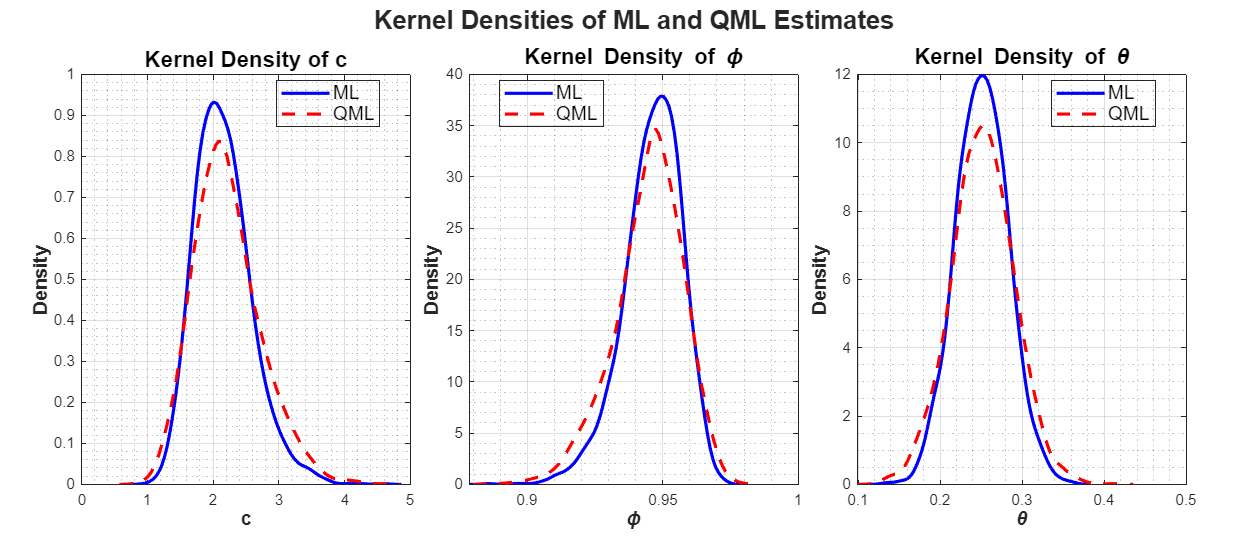

%%% Task 6.2: we compute kernel densities and visualize the densities of ML and QML estimators
params = {'c', '\phi', '\theta'};  

colors = {'b', 'r'};        
lineStyles = {'-', '--'};   

% Plotting
figure('Color', 'w', 'Position', [100, 100, 1400, 600]); 

t = tiledlayout(1, 3, 'TileSpacing', 'Compact', 'Padding', 'Compact');

for i = 1:3  
    nexttile;  

    % Now we compute kernel densities
    [ML_density, ML_x] = ksdensity(ML_estimates(:, i));   
    [QML_density, QML_x] = ksdensity(QML_estimates(:, i));

    % Now we plot densities of corresponding ML and QML estimators
    plot(ML_x, ML_density, 'LineWidth', 2, 'Color', colors{1}, 'LineStyle', lineStyles{1});
    hold on;

    plot(QML_x, QML_density, 'LineWidth', 2, 'Color', colors{2}, 'LineStyle', lineStyles{2});

    title(['Kernel Density of ', params{i}], 'FontSize', 14, 'FontWeight', 'bold'); 
    xlabel(params{i}, 'FontSize', 12, 'FontWeight', 'bold'); 
    ylabel('Density', 'FontSize', 12, 'FontWeight', 'bold'); 

    legend({'ML', 'QML'}, 'Location', 'Best', 'FontSize', 12, 'Color', 'none');

    grid on;
    grid minor;

    hold off;
end

sg = sgtitle('Kernel Densities of ML and QML Estimates', 'FontSize', 16, 'FontWeight', 'bold');

current_pos = sg.Position;

Unrecognized method, property, or field 'Position' for class 'matlab.graphics.layout.Text'.

sg.Position = [current_pos(1), current_pos(2) + 0.05, current_pos(3)];

## Task 7: Confidence Interval Analysis

% Now we will compute 95% confidence intervals for ML estimates across K simulations 
% and determine the proportion of true parameters falling within these intervals

% True parameter values 
true_params = [2; 0.95; 0.25; 4]; 

% ML estimates and standard errors
c_ML = ML_estimates(:, 1);
phi_ML = ML_estimates(:, 2);
theta_ML = ML_estimates(:, 3);
nu_ML = ML_estimates(:, 4);

se_c = ML_standard_errors(:, 1);
se_phi = ML_standard_errors(:, 2);
se_theta = ML_standard_errors(:, 3);
se_nu = ML_standard_errors(:, 4);

% 95% confidence intervals
lower_c = c_ML - 1.96 * se_c;
upper_c = c_ML + 1.96 * se_c;

lower_phi = phi_ML - 1.96 * se_phi;
upper_phi = phi_ML + 1.96 * se_phi;

lower_theta = theta_ML - 1.96 * se_theta;
upper_theta = theta_ML + 1.96 * se_theta;

lower_nu = nu_ML - 1.96 * se_nu;
upper_nu = nu_ML + 1.96 * se_nu;

% We test how often true parameters lie within the confidence intervals
c_in_CI = sum((true_params(1) >= lower_c) & (true_params(1) <= upper_c));
phi_in_CI = sum((true_params(2) >= lower_phi) & (true_params(2) <= upper_phi));
theta_in_CI = sum((true_params(3) >= lower_theta) & (true_params(3) <= upper_theta));
nu_in_CI = sum((true_params(4) >= lower_nu) & (true_params(4) <= upper_nu));

% Computing percentages
c_coverage = (c_in_CI / 2500) * 100;
phi_coverage = (phi_in_CI / 2500) * 100;
theta_coverage = (theta_in_CI / 2500) * 100;
nu_coverage = (nu_in_CI / 2500) * 100;

disp('95% Confidence Interval Coverage Results:');

95% Confidence Interval Coverage Results:


-----------------------------------------


fprintf('Parameter c (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(1), c_coverage);

Parameter c (true value = 2.00): 94.72% of intervals include the true value


fprintf('Parameter φ (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(2), phi_coverage);

Parameter φ (true value = 0.95): 94.60% of intervals include the true value


fprintf('Parameter θ (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(3), theta_coverage);

Parameter θ (true value = 0.25): 94.28% of intervals include the true value


fprintf('Parameter ν (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(4), nu_coverage);

Parameter ν (true value = 4.00): 95.96% of intervals include the true value


-----------------------------------------
